# PID Synthesis of Motor 1

T = 0.02;
z = tf('z', T);
s = tf('s');

Gpz = ((0.2918*z^(2) + -0.02748*z + 0.01179)/(z^(3) - 0.6419*z^(2) + 0.08843*z))

Gpz =
 
  0.2918 z^2 - 0.02748 z + 0.01179
  --------------------------------
    z^3 - 0.6419 z^2 + 0.08843 z
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model Properties


Gps = d2c(Gpz, 'tustin')

Gps =
 
  -0.1913 s^3 - 13.23 s^2 + 1641 s + 1.596e05
  -------------------------------------------
    s^3 + 205.4 s^2 + 1.312e04 s + 2.581e05
 
Continuous-time transfer function.
Model Properties


Gps_FO = (0.6178*exp(-0.0093*s))/(0.0312*s+1)

Gps_FO =
 
                      0.6178
  exp(-0.0093*s) * ------------
                   0.0312 s + 1
 
Continuous-time transfer function.
Model Properties


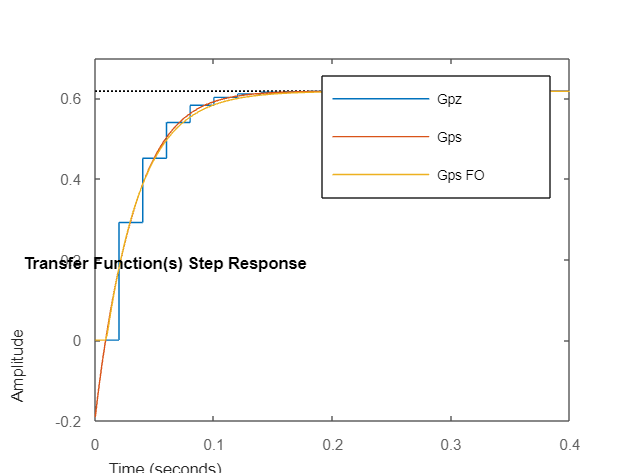

step(Gpz)
hold on
step(Gps)
step(Gps_FO)
legend('Gpz', 'Gps','Gps FO')
title('Transfer Function(s) Step Response')
hold off

For the the first order transfer function in continuous time, a two point analysis of the Motor 1 transfer function was made to determine the K, Tau and Theta values. 


$$\mathrm{Gp}\left(s\right)=\frac{{\mathrm{Ke}}^{\theta s} }{\tau s+1}$$



$$K=0\ldotp 6178$$



$$\tau =0\ldotp 0312;$$



$$\theta =0\ldotp 0093;$$


%Computing of the PID paramters (ITAE)
K = 0.6178;
Tau = 0.0312;
Theta = 0.0093;

%ITAE

a = 0.965;
b = -0.85;
c = 0.796;
d = -0.147;
e = 0.308;
f = 0.929;


Kp = (1/K)*(a*(Theta/Tau)^b);
Taui = (Tau)/(c+d*(Theta/Tau));
Taud = (Tau)*(e*(Theta/Tau)^f);

Kpz = Kp-(Kp*T)/(2*Taui)

Kpz = 3.3166

Kiz = (Kp*T)/Taui

Kiz = 2.1072

Kdz = (Kp*Taud)/T

Kdz = 0.6821